生成噪声fs1,fs2,Fp1,Fp2-1,2,3,4

global T
T = 300;

global rs
global rp
global srp
global k
global srs
global Fp

rs = 1;
rp = 100;
srp = sqrt(rp);
k = 0.1;
srs = sqrt(rs);
Fp = 1;
Fth = rs*srp/4/k;

global f
f = 0.5.*randn(4,T)

f =    -0.2873   -0.0587   -0.0621   -0.3890    0.8811    0.7990    0.0445   -0.5674    0.9454    0.4062   -0.3126    0.2358   -0.0820   -0.0340    0.7599   -0.1513   -0.2530   -0.3796   -0.7488   -0.0730   -0.1010    0.1748   -0.7639   -0.2099   -0.0392    0.1272    0.9794    0.3606   -0.5253   -0.5963   -0.0663    0.7728   -0.5078   -0.4272    0.2303   -0.1884    1.2316    0.7061   -0.6238   -1.0630   -0.3183   -0.0296    0.1799    0.2617   -1.0225   -0.5564    0.3563   -1.0916    0.4119    0.5296
    0.5492   -0.0857    0.2666   -0.1755   -0.5589    0.0837    0.4575   -0.4118   -0.7653   -1.3562    0.5177    0.1569   -0.6209    0.3159    0.8575   -0.2787   -0.0615    0.8233   -1.3190    1.0882   -0.9267    0.6917   -0.1619   -0.5284    0.9793    0.3427    0.1890   -0.5297    0.0213    0.6808    0.0927    0.5989   -0.0071    0.2078    0.3778   -0.1248    0.9141   -0.3061    0.7871    0.1452   -0.4754   -0.1108   -0.3749   -0.6770   -1.3771   -0.1131   -0.0999   -0.4999    0.3371   -0

% Verify 
stats1 = [mean(f(1,:).^2) mean(f(2,:).^2) mean(f(3,:).^2) mean(f(4,:).^2)]

stats1 =     0.2448    0.3003    0.2400    0.2307


stats2 = [mean(f(1,:).*f(3,:)) mean(f(2,1:T/2).*f(2,T/2+1:T))]

stats2 =    -0.0089   -0.0317



Fp = 1.3*Fth;
figure;
% hold on;

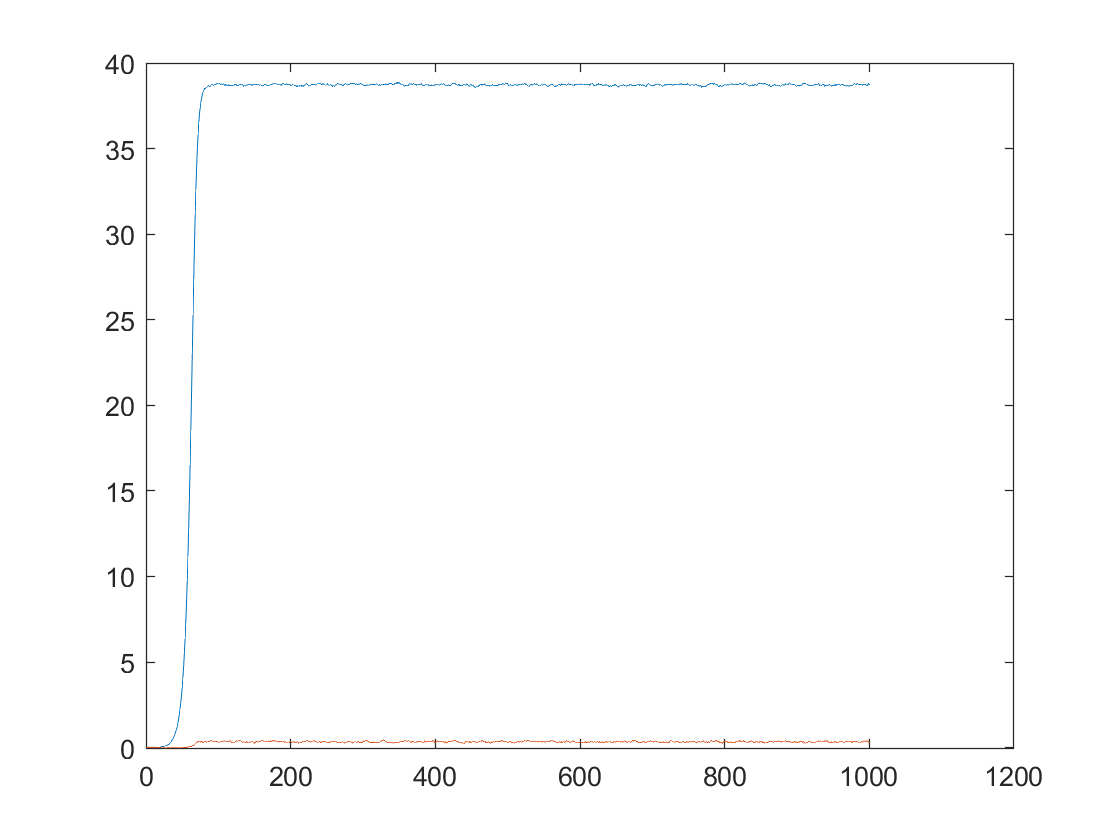

plot(y);

var(y(length(t)-100:length(t),1))

ans = 0.0018

var(y(length(t)-100:length(t),2))

ans = 0.0011

Fp = 1.0*Fth;
[t,y] = ode45(@eq5,[0:1000],[0 0]);

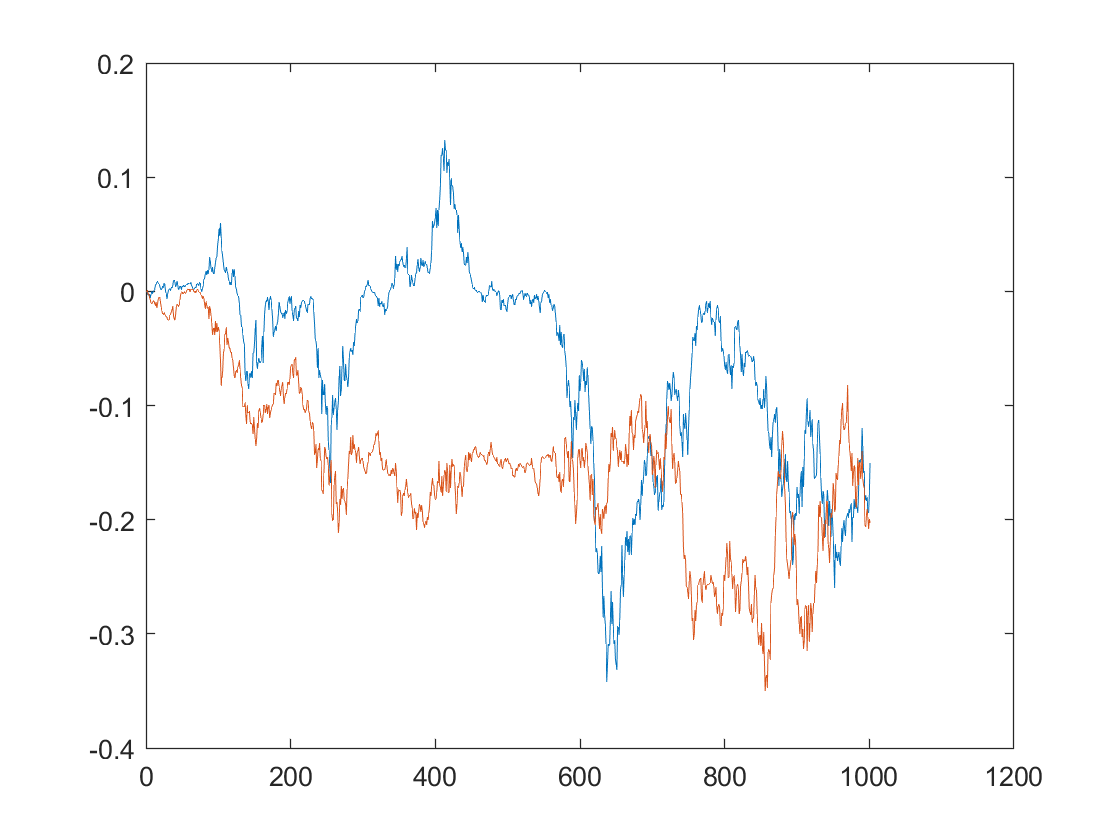


plot(y);


var(y(length(t)-100:length(t),1))

ans = 0.0013

var(y(length(t)-100:length(t),2))

ans = 0.0036


mean([;])

ans = NaN

tem_r = []


tem =

     []



tem_i = []


tem2 =

     []



rr = []
ri = []
Y=[]


Y =

     []



Fp = 1*Fth;
for i = 1:20
    [t,y] = ode45(@eq5,[0:800],[0 0])
    tem_r = [tem_r y(:,1)];
    tem_i = [tem_i y(:,2)];
end
rr = [rr ; tem_r];
ri = [ri ; tem_i];

y(length(t),:)

tem
tem2
var(tem(:,2)) % 0.0815var(tem(:,1)) % 0.0815var(tem(:,1)) % 0.0815

p = Fp/Fth

% function dy = eq5(t,A)
% global rs
% global rp
% global srp
% global k
% global srs
% global Fp
% global f
% global T
% 
%     dy = zeros(2,1);
%     dy(1) = -rs/2.*A(1)...
%         +2*k/srp*Fp*A(1)...
%         -k.*k/rp*A(1)^3     +k^2/rp*A(1)*A(2)^2 -2*k*k/rp*A(1)*A(2)^2 ...
%         +2*k/srp*A(1)*f(1,randi(T)) +2*k/srp*A(2)*f(2,randi(T))...
%         +srs*(f(3,randi(T)));
%     dy(2) = -rs/2*A(2)...
%         -2*k/srp*Fp*A(2)...
%         +k*k/rp*A(1)^2+A(2) -k^2/rp*A(2)^3      -2*k*k/rp*A(1)^2*A(2)...
%         -2*k/srp*A(1)*f(2,randi(T)) -2*k/srp*A(2)*f(1,randi(T))...
%         +srs*(f(4,randi(T)));
% end

function dy = eq5(t,A)
global rs
global rp
global srp
global k
global srs
global Fp
% global f
% global T

    dy = zeros(2,1);
    dy(1) = -rs/2.*A(1)...
        +2*k/srp*Fp*A(1)...
        -k.*k/rp*A(1)^3     +k^2/rp*A(1)*A(2)^2 -2*k*k/rp*A(1)*A(2)^2 ...
        +2*k/srp*A(1)*0.5.*randn(1,1) +2*k/srp*A(2)*0.5.*randn(1,1)...
        +srs*0.5.*randn(1,1);
    dy(2) = -rs/2*A(2)...
        -2*k/srp*Fp*A(2)...
        +k*k/rp*A(1)^2+A(2) -k^2/rp*A(2)^3      -2*k*k/rp*A(1)^2*A(2)...
        -2*k/srp*A(1)*0.5.*randn(1,1) -2*k/srp*A(2)*0.5.*randn(1,1)...
        +srs*0.5.*randn(1,1);
end